# Hold-out validation of TA1415 model

## Open the model

modelName = 'TA1415';
open_system(modelName)
set_param(modelName + "/Manual Switch1",'sw','0')

## Estimation problem

You use measured data to estimate the model parameters.

Input is IPTG concentration (step).

Measured output data is concentation in the culture medium

- OD600

- IPA

Parameters: six kinetic parameters

## Define the estimation experiments

Load the measured data.

outputData = cell(15,1);
for expIdx = 1:15
    outputData{expIdx} = readtable("TA1415Data.xlsx","Sheet",expIdx);
end

Create the input data.

inputTime = [0 6 6 9 9 12 12 15 15 69]';
input = cell(15,1);

for i = 0:4
    input{5*i + 1} = [1 1 1 1 1 1 1 1 1 1]';
    input{5*i + 2} = [0 0 1 1 1 1 1 1 1 1]';
    input{5*i + 3} = [0 0 0 0 1 1 1 1 1 1]';
    input{5*i + 4} = [0 0 0 0 0 0 1 1 1 1]';
    input{5*i + 5} = [0 0 0 0 0 0 0 0 1 1]';
end

inputData = cell(15,1);
for expIdx = 1:15
    inputData{expIdx} = table;
    inputData{expIdx}.Time = inputTime;
    inputData{expIdx}.IPTG = input{expIdx};
end

Create an experiment object to store the measured input/output data. 

Exp = sdo.Experiment(modelName);
% sdo.Experiment object
% The OutputData property and other properties are empty

Create Simulink.SimulationData.Signal objects to store the measured outputs.

% IPTG input
IPTGSignal = Simulink.SimulationData.Signal;
IPTGSignal.Name = 'IPTG';
IPTGSignal.BlockPath = modelName + "/IPTG";
IPTGSignal.PortType  = 'inport';
IPTGSignal.PortIndex = 1;
IPTGSignal.Values    = timeseries(inputData{1}.IPTG,inputData{1}.Time);

Exp.InputData = IPTGSignal; % add the signal object to the experiment

% OD600 output
OD600Signal = Simulink.SimulationData.Signal;
OD600Signal.Name = 'OD600';
OD600Signal.BlockPath = modelName + "/Gain";
OD600Signal.PortType = 'outport';
OD600Signal.PortIndex = 1;
OD600Signal.Values = timeseries(outputData{1}.OD600,outputData{1}.Time);

% Glucose output
% GlucoseSignal = Simulink.SimulationData.Signal;
% GlucoseSignal.Name = 'Glucose';
% GlucoseSignal.BlockPath = modelName + "/Gain2";
% GlucoseSignal.PortType = 'outport';
% GlucoseSignal.PortIndex = 1;
% GlucoseSignal.Values = timeseries(outputData{1}.Glucose,outputData{1}.Time);

% IPA output
IPASignal = Simulink.SimulationData.Signal;
IPASignal.Name = 'IPA';
IPASignal.BlockPath = modelName + "/Demux";
IPASignal.PortType = 'outport';
IPASignal.PortIndex = 5;
IPASignal.Values = timeseries(outputData{1}.IPA,outputData{1}.Time);

Exp.OutputData = [OD600Signal; IPASignal]; % add the signal object to the experiment

Define the five experiments.

Exp = [Exp;Exp;Exp;Exp;Exp;...
        Exp;Exp;Exp;Exp;Exp;...
        Exp;Exp;Exp;Exp;Exp];
for expIdx = 1:15
    Exp(expIdx).InputData.Values = timeseries(inputData{expIdx}.IPTG,inputData{expIdx}.Time);
    Exp(expIdx).OutputData(1).Values = timeseries(outputData{expIdx}.OD600,outputData{expIdx}.Time);
    % Exp(expIdx).OutputData(2).Values = timeseries(outputData{expIdx}.Glucose,outputData{expIdx}.Time);
    Exp(expIdx).OutputData(2).Values = timeseries(outputData{expIdx}.IPA,outputData{expIdx}.Time);
end

## Specify the parameters to estimate

Specify bounds for the parameter values based on the structure of the model.

parameters = readtable("Parameters_TA1415.xlsx");
p = sdo.getParameterFromModel(modelName,parameters.Name);

% the output argument 'p' is a Param.Continuous object
% scaling factor can be specified in the Param.Continuous object

for paramIdx = 1:height(parameters)
    p(paramIdx).Value = parameters.InitialGuess(paramIdx);
    p(paramIdx).Minimum = parameters.Minimum(paramIdx);
    p(paramIdx).Maximum = parameters.Maximum(paramIdx);
    p(paramIdx).Scale = parameters.Scale(paramIdx);
    p(paramIdx).Free = parameters.Free(paramIdx);
end

## Compare the measured output and the simulated output with the initial guess

Set the initial guess of the parameters to the experiment object and simulate. 

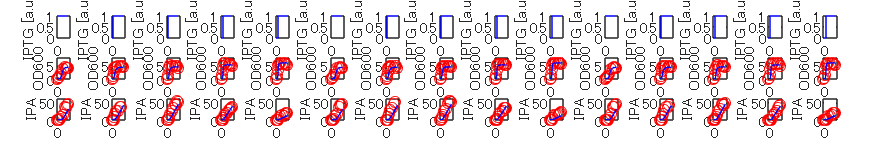

Exp = setEstimatedValues(Exp,p);
figure('Position', [100 100 1500 250]);
t = tiledlayout(3,15,'Padding','Compact','TileSpacing','tight');
t.TileIndexing = 'columnmajor';
for expIdx = 1:15
    plotSimTA1415(Exp,expIdx);
end

Check the objective function.

Simulator = createSimulator(Exp(1));
Error = estimation_Objective(p,Simulator,Exp,1:15,1:2,0);
fx = Error.F'*Error.F

fx = 13.2864

## Configure the simulator and model for Fast Restart

The simulator controls whether the model is simulated using fast restart or not. The `fastRestart` command is used to configure the simulator to use Fast Restart. 

The model uses a variable-step solver, and may not output values at the times in the measured experiment data. To output values at the times of the measured data, use the `set_param` command to specify the model logging output times as a workspace variable. In the estimation objective function, the variable is then used to specify output times to be the same as the measured experiment data. The model `OutputTimes` is set before configuring the simulator for fast restart, as once the model is configured for fast restart, the model logging configuration can not change.

Simulator = createSimulator(Exp(1));
modelName = Simulator.ModelName;
set_param(modelName,'OutputOption','SpecifiedOutputTimes', ...
    'OutputTimes','OutputTimesValues');
% 'OutputTimesValues' will be created in the objective function and assigned to the base
% workspace
Simulator = fastRestart(Simulator,'on');

The simulator can now be used during estimation, and the model will be simulated using fast restart.

## Define the estimation objective function

Create an estimation objective function to evaluate how closely the simulation output, generated using the estimated parameter values, matches the measured data.

Use an anonymous function with one input argument that calls the `cellCultureModel_Objective` function. Pass the anonymous function to `sdo.optimize`, which evaluates the function at each optimization iteration.

lambda = 0;         % regularization parameter
expToUse = 1:15;     % training data set
outputToUse = 1:2;  % two outputs (OD600,IPA)
% estFcn = @(p) estimation_Objective(p,Simulator,Exp,expToUse,outputToUse,lambda);

## Estimate the parameters

Use the `sdo.optimize` function to estimate the actuator parameter values and initial state. 

Specify the optimization options. The estimation function `sdoAircraftEstimation_Objective` returns the error residuals between simulated and experimental data and does not include any constraints, making this problem ideal for the `lsqnonlin` solver.

options = sdo.OptimizeOptions;
options.Method = 'lsqnonlin';
options.UseParallel = 1;
options.OptimizedModel = modelName;

Create a cluster object

% close the model!
c = parcluster

c = 

 Generic Cluster

    プロパティ: 

                   Profile: cc21dev0_cluster_short R2022a
                  Modified: false
                      Host: LAPTOP-5PV3VUVE
                NumWorkers: 100
                NumThreads: 1

        JobStorageLocation: C:\Users\tomok\AppData\Roaming\MathWorks\MATLAB\3p_cluster_jobs\default_cluster\LAPTOP-5PV3VUVE\R2022a\nonshared
         ClusterMatlabRoot: /usr/local/MATLAB/R2022a/
           OperatingSystem: unix

   RequiresOnlineLicensing: false
     PluginScriptsLocation: C:\Users\tomok\MATLAB\slurm_integration\IntegrationScripts\default_cluster
      AdditionalProperties: 

Create a job and submit it to the cluster. 

pathToData = pwd

pathToData = 'C:\Users\tomok\MATLAB\Projects\Soma2014'

for condIdx = 1:5 % change manually!
    job(condIdx) = batch(c,@parallelEstimation,2,{p,options,Exp,Simulator,condIdx}, ...
                "Pool",6, ...
                "CurrentFolder",'.', ...
                "AdditionalPaths",pathToData, ...
                "AttachedFiles",{'TA1415.slx'} ...
                );
end

additionalSubmitArgs = '--ntasks=7 --cpus-per-task=1 --ntasks-per-core=1 --mem-per-cpu=7300MB -p cluster_short --time 4:00:00'

additionalSubmitArgs = '--ntasks=7 --cpus-per-task=1 --ntasks-per-core=1 --mem-per-cpu=7300MB -p cluster_short --time 4:00:00'

additionalSubmitArgs = '--ntasks=7 --cpus-per-task=1 --ntasks-per-core=1 --mem-per-cpu=7300MB -p cluster_short --time 4:00:00'

additionalSubmitArgs = '--ntasks=7 --cpus-per-task=1 --ntasks-per-core=1 --mem-per-cpu=7300MB -p cluster_short --time 4:00:00'

additionalSubmitArgs = '--ntasks=7 --cpus-per-task=1 --ntasks-per-core=1 --mem-per-cpu=7300MB -p cluster_short --time 4:00:00'

Check the state of the job.

for condIdx = 1:5 % change manually!
    sprintf('job %d is %s \n',condIdx ,job(condIdx).State)
    diary(job(condIdx))
end

ans =     'job 1 is running 
     '


--- ダイアリ開始 ---

modelName =

    'TA1415'


validSet =

     1     6    11


trainSet =

     2     3     4     5     7     8     9    10    12    13    14    15

Configuring parallel workers for optimization...
Parallel workers configured for optimization.

 Optimization started 21-Feb-2023 23:07:07

                                          First-order 
 Iter F-count        f(x)      Step-size  optimality
    0     17       10.328            1                                         
    1     34      8.22388        0.106         23.7
    2     51      4.36778       0.3025         7.32
    3     68      4.36778       0.6554         7.32
    4     85      3.76945       0.1638         3.13
    5    102      3.76945       0.3277         3.13

--- ダイアリ終了 ---


ans =     'job 2 is failed 
     '


--- ダイアリ開始 ---
--- ダイアリ終了 ---


ans =     'job 3 is finished 
     '


--- ダイアリ開始 ---

modelName =

    'TA1415'


validSet =

     3     8    13


trainSet =

     1     2     4     5     6     7     9    10    11    12    14    15

Configuring parallel workers for optimization...
Parallel workers configured for optimization.

 Optimization started 21-Feb-2023 23:07:16

                                          First-order 
 Iter F-count        f(x)      Step-size  optimality
    0     17      10.9576            1                                         
    1     34      6.89834       0.1569         23.5
    2     51      4.80424       0.1717         10.1
    3     68      4.80424       0.3471         10.1
    4     85      4.50011      0.08679         3.89
    5    102      4.16307       0.1736         7.98
    6    119        3.841       0.2071         25.1
    7    136      3.50865      0.09954         6.55
    8    153      3.45666       0.1736         57.2
    9    170      3.21963      0.04339         4.63
   10    187      3.16817      0.08679   

ans =     'job 4 is finished 
     '


--- ダイアリ開始 ---

modelName =

    'TA1415'


validSet =

     4     9    14


trainSet =

     1     2     3     5     6     7     8    10    11    12    13    15

Configuring parallel workers for optimization...
Parallel workers configured for optimization.

 Optimization started 21-Feb-2023 23:07:20

                                          First-order 
 Iter F-count        f(x)      Step-size  optimality
    0     17      12.6152            1                                         
    1     34      12.2973       0.4319         54.1
    2     51      7.67656      0.06494         15.9
    3     68       5.0672        0.108         5.61
    4     85      3.07784       0.2159         2.72
    5    102      2.55135        0.164         8.61
    6    119       2.3738       0.1932         11.8
    7    136      2.25265       0.1286         2.45
    8    153      2.23552      0.06977        0.408
    9    170      2.22682      0.04094         1.02
   10    187      2.22595    0.0002215   

ans =     'job 5 is finished 
     '


--- ダイアリ開始 ---

modelName =

    'TA1415'


validSet =

     5    10    15


trainSet =

     1     2     3     4     6     7     8     9    11    12    13    14

Configuring parallel workers for optimization...
Parallel workers configured for optimization.

 Optimization started 21-Feb-2023 23:07:24

                                          First-order 
 Iter F-count        f(x)      Step-size  optimality
    0     17      9.78421            1                                         
    1     34      3.21481       0.2108         6.15
    2     51      2.40965       0.1175         1.99
    3     68      2.34907      0.04198        0.649
    4     85      2.34907       0.4832        0.649
    5    102      2.23782       0.1208         1.88
    6    119      2.19909      0.08791         1.02
    7    136      2.19408     0.003865        0.734
    8    153      2.19408       0.2416        0.734
    9    170      2.14291       0.0604         1.11
   10    187      2.09477       0.1208   

Get the printed log in the cluster.

% getReport(job.Tasks(1).Error)

Fetch the results from the cluster.

for condIdx = 1:5 % change manually!
    if job(condIdx).State == "finished"
        result = fetchOutputs(job(condIdx));
        pOpts_TA1415{condIdx,1} = result{1};
        optInfos_TA1415{condIdx,1} = result{2};
    end
end

Save the optimized parameters and the optimization report.

save('pOpts_TA1415','pOpts_TA1415')
save('optInfos_TA1415','optInfos_TA1415')

Delete the job from the cluster.

delete(job)

Clear the job object from the base workspace of the client.

clear job

## Restore the model

Restore the simulator fast restart settings. This clears the logging and other settings used for the optimization problem. 

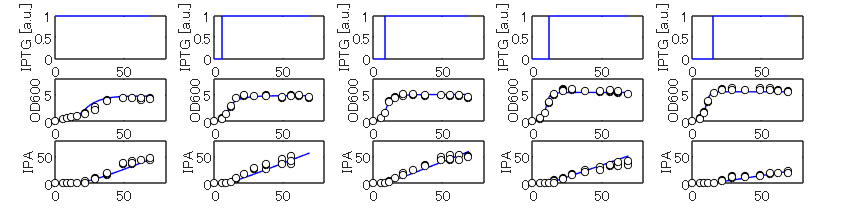

Simulator = fastRestart(Simulator,'off');

set_param(modelName,'OutputOption','RefineOutputTimes','OutputTimes','[]');

## Calculate coefficient of determination (R2)

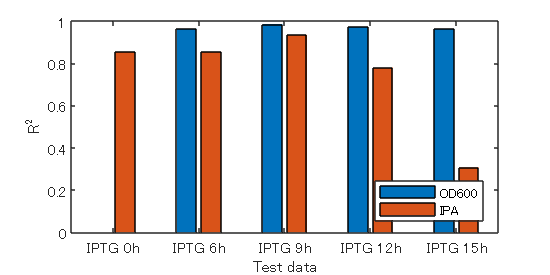

Simulator = createSimulator(Exp(1));
R2_TA1415 = zeros(15,2);
for expIdx = 1:15 % test data set
    condIdx = mod(expIdx + 4,5) + 1;
    R2_TA1415(expIdx,:) = rSquared(pOpts_TA1415{condIdx,1},Simulator,Exp,expIdx,1:2);
end

R2_TA1415_OD600 = R2_TA1415(:,1);
R2_TA1415_IPA = R2_TA1415(:,2);

R2_TA1415_OD600_mean = mean(reshape(R2_TA1415_OD600,5,3),2);
R2_TA1415_IPA_mean = mean(reshape(R2_TA1415_IPA,5,3),2);

% all conditions
figure('Position', [100 100 400 200]);
b = bar([R2_TA1415_OD600_mean,R2_TA1415_IPA_mean]);
xticklabels({'IPTG 0h' 'IPTG 6h' 'IPTG 9h' 'IPTG 12h' 'IPTG 15h'})
xlabel('Test data')
ylabel('R^2')
ylim([0 1])
legend({'OD600' 'IPA'},'Location','Southeast')

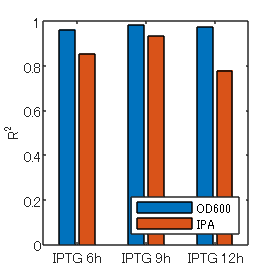

% interpolation conditions
figure('Position', [100 100 200 200]);
b = bar([R2_TA1415_OD600_mean(2:4),R2_TA1415_IPA_mean(2:4)]);
xticklabels({'IPTG 6h' 'IPTG 9h' 'IPTG 12h'})
% xlabel('Test data')
ylabel('R^2')
ylim([0 1])
legend({'OD600' 'IPA'},'Location','Southeast')

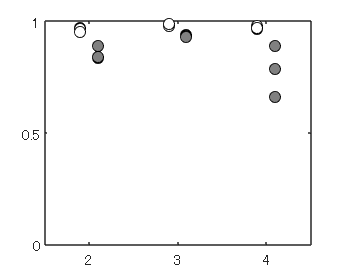

cond = [1:5,1:5,1:5]';
d = 0.1;

figure('Position', [100 100 250 200]);
plot(cond-d,R2_TA1415_OD600,'ko','MarkerFaceColor','w')
hold on
plot(cond+d,R2_TA1415_IPA,'ko','MarkerFaceColor',[0.5 0.5 0.5])
xlim([1.5 4.5])
xticks([2 3 4])
ylim([0 1])
yticks([0 0.5 1])
hold off

% sdo.setValueInModel('TA1415',pOpt);

Close the model.

bdclose(modelName)

*Copyright Tomoki Ohkubo@NAIST*